# 三体相互作用阈值随B的变化

## 生成数据

clear
warning off
dbstop if error
tic
options=optimset("Display","off");
[kfasneg,eigenvalue]=deal(linspace(0.15,0.2,20));

a=0;
B=linspace(0,1);

for i = 1:length(kfasneg)
    eigenvalue(i)=borromeansolver(a,kfasneg(i),40/6,B(1));
    toc
    if eigenvalue(i)>0
        break
    end
end

时间已过 83.915504 秒。
时间已过 180.010109 秒。
时间已过 273.651146 秒。
时间已过 363.842802 秒。
时间已过 452.178897 秒。
时间已过 546.087569 秒。
时间已过 640.948902 秒。
时间已过 734.787840 秒。
时间已过 828.670563 秒。
时间已过 918.528205 秒。
时间已过 1007.506719 秒。
时间已过 1096.634892 秒。
时间已过 1184.430221 秒。
时间已过 1279.915341 秒。
时间已过 1370.620094 秒。
时间已过 1460.193745 秒。
时间已过 1547.271940 秒。
时间已过 1644.785789 秒。
时间已过 1738.414332 秒。
时间已过 1835.526336 秒。



eigs1=zeros(1,100);

eigs1(1)=fsolve(@(x) borromeansolver(a,x,40/6,B(1)),eigenvalue(i),options);
for i=2:length(eigs1)
    try
        eigs1(i)=fsolve(@(x) borromeansolver(a,x,40/6,B(i)),eigs1(i-1),options);
        toc
       
    catch ME
        eigs1=eigs1(1:i);
        
        B=B(1:i);
        break;
        
    end
end

时间已过 2562.222872 秒。
时间已过 2934.717002 秒。
时间已过 3298.023450 秒。


t=toc;
plot(B,eigs1)
fig=gcf;
saveas(fig,'kfasnegvsB.bmp')
sendEmail('mission complete',strcat('total time :',num2str(t),'s'),'kfasnegvsB.bmp')

## 测试

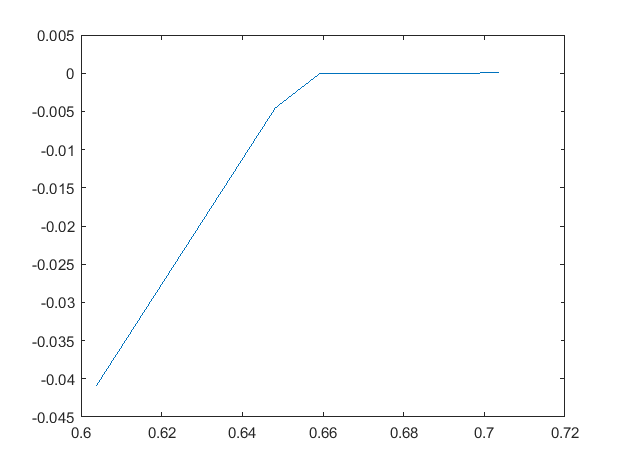

j=90;
Btest=B(j);
kfasnegtest=eigs1(j);

kfasnegloop=linspace(kfasnegtest-0.05,kfasnegtest+0.05,10);
output=kfasnegloop;
for i=1:length(kfasnegloop)
    output(i)=borromeansolver(0,kfasnegloop(i),40/6,Btest);
end
figure
plot(kfasnegloop,output)